# DTMC Stochastic SIR Model

Unlike deterministic models, a **stochastic model** is governed by a stochastic element, which can randomly vary as the simulation is run multiple times. In other words, the term **stochasticity** refers to the property of a system in which the randomness of reality is taken into account, as opposed to analogous deterministic systems. Despite the randomness o the results, a precise model may be reached if various simulations are done.

Another characteristic of a stochastic model is that it obeys to the **Markov rule**, which states that the values of the model at the current moment exclusively depend on its values at the previous moment. If the analysed variables take on discrete values, the model can be called a **Markov chain**:

$Prob\{I(t_n+1) | I(t_0), I(t_1), ..., I(t_n)\}=Prob\{I(t_{n+1}) | I(t_n)\}$.

What makes stochastic models advantageous in Epidemiology is that they can predict the dynamics of a disease outbreak in terms of probabilities. For instance, if a large number of simulations give overlapping curves, whereas only few simulations produce other results, the pandemics will likely proceed as those repeating curves suggest.

In a DTMC (Discrete Time Markov Chain) SIS epidemic model, discrete random variables are defined for a discrete time scale where $t=\in\{0,\Delta t,2\Delta t, ....\}$ and $S(t), I(t) \in \{1,2,...N\}$. In this model, there is only one independent, random variable, $I(t)$, since $S(t)=N-I(t)
$. 

Considering $I(t)= i  \text{ and } I(t+\Delta t)=j, p{_j}{_i} \text{ would be the probability of }i \rightarrow j$. 


$$p{_j}{_i}(t+\Delta t,t)=Prob\{I(t+\Delta t)=j|I(t)=i\}$$


The stochastic SIS model is said to be time homogeneous since the transition probability $p{_j}{_i}(t+\Delta t,t) \text{ does not depend on } t \text{ but only one } \Delta t, p{_j}{_i}(\Delta t). $

To reduce the number of transitions for each change in time, the time step $\Delta t$ is chosen sufficiently small in order for the number of infected individuals changes by one at the most.


$$i\rightarrow i+1,\text{ }i\rightarrow i-1, \text{ or }i\rightarrow i$$


For each possible transitioin, a probability must be defined, which consist of the rates multiplied by $\Delta t$. 


$$p{_j}{_i}(\Delta t) = 
     \begin{cases}
      \frac{\beta i(N-i)}{N}\Delta t,&\quad j=i+1\\
       (b+\gamma)i\Delta t,&\quad j=i-1\\
       1-[\frac{\beta i(N-i)}{N}+(b+\gamma )i]\Delta t,&\quad j=i\\
       0,&\quad j\neq i+1,i,i-1
     \end{cases}$$


All the transition probabilities are arranged in a Matrix T($\Delta t$) where the number of columns and rows is $N+1$. T($\Delta t$) is a stochastic matrix, meaning that the sum of all columns is equal to 1. 

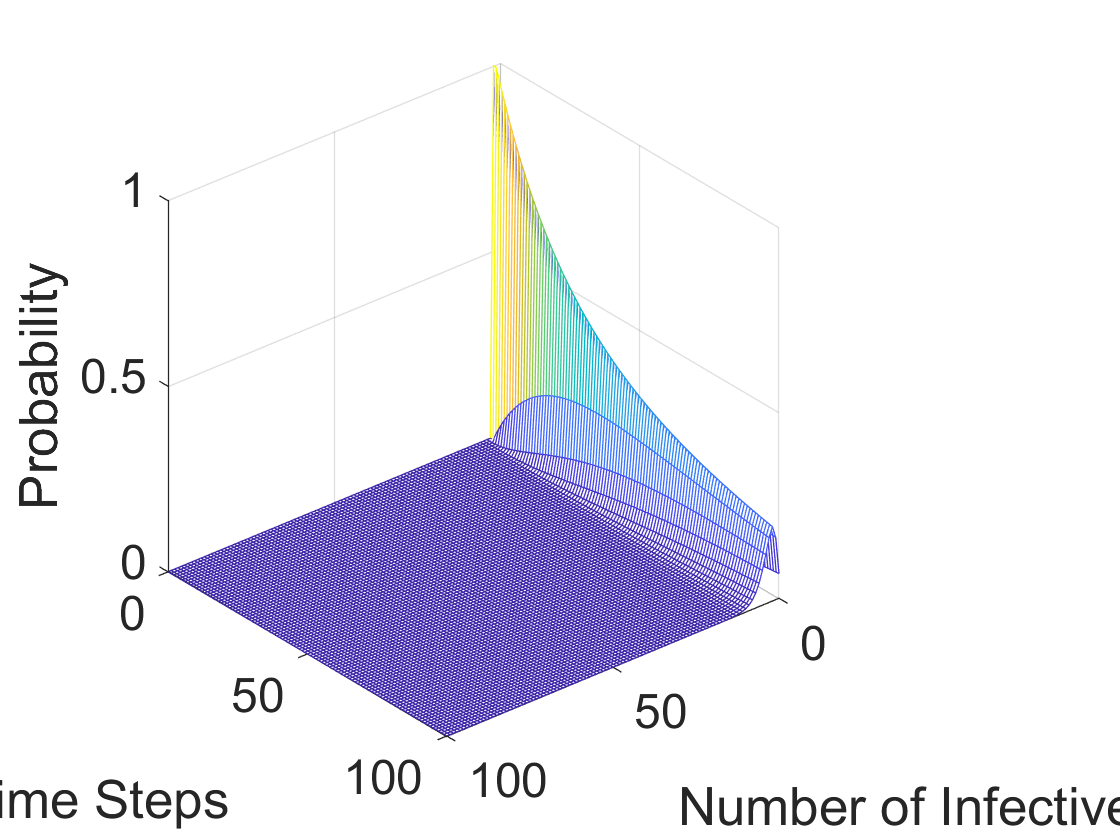

% MatLab Program # 1
% Discrete Time Markov Chain
% SIS Epidemic Model
% Transition Matrix and Graph of Probability Distribution

clear all
set(gca,'FontSize',18);
set(0,'DefaultAxesFontSize',18);

time=100;

N=100; % Total population size

dtt=0.01; % Time step
beta=1*dtt;
b=0.25*dtt;
gama=0.2*dtt;


en=1; % plot every enth time interval
T=zeros(N+1,N+1); % T is the transition matrix, defined below

v=linspace(0,N,N+1);
p=zeros(time+1,N+1);

p(1,3)=1; % Two individuals initially infected.

bt=beta*v.*(N-v)/N;
dt=(b+gama)*v;

for i=2:N % Define the transition matrix
    T(i,i)=1-bt(i)-dt(i); % diagonal entries
    T(i,i+1)=dt(i+1); % superdiagonal entries
    T(i+1,i)=bt(i); % subdiagonal entries
end

T(1,1)=1;
T(1,2)=dt(2);
T(N+1,N+1)=1-dt(N+1);

for t=1:time
    y=T*p(t,:)';
    p(t+1,:)=y';
end

pm(1,:)=p(1,:);

for t=1:time/en;
    pm(t+1,:)=p(en*t,:);
end

ti=linspace(0,time,time/en+1);
st=linspace(0,N,N+1);
mesh(st,ti,pm);
xlabel('Number of Infectives');
ylabel('Time Steps');
zlabel('Probability');
view(140,30);
axis([0,N,0,time,0,1]);